# 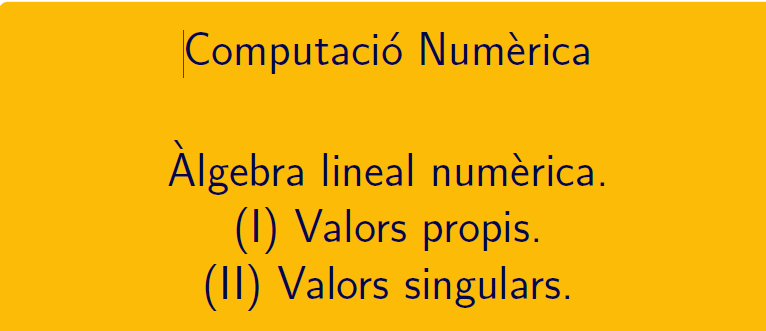

============================================================================

# Pràctica 5. Mètode de les potències. 

## 2.2 Valors i vectors propis d'una matriu. Mètode de la potència.

### Part I. Algorismes i joc de proves

#### Exemple 1. Mètode de la potència per al valor propi de mòdul més gran

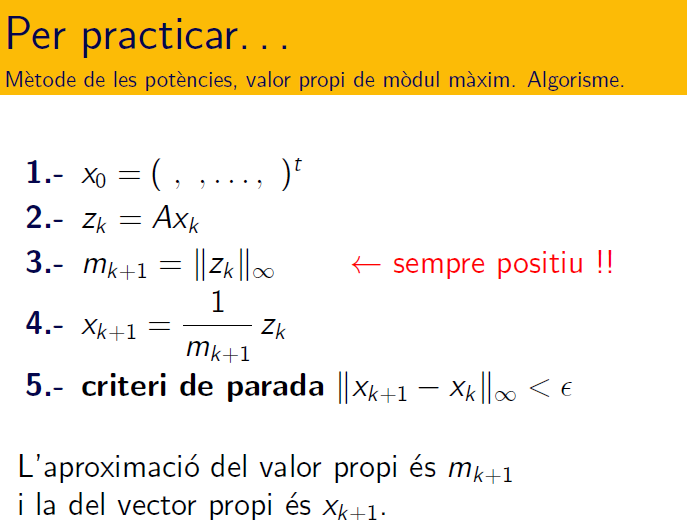

Calculeu, amb quatre xifres significatives, el valor propi dominant de la matriu:       $A=\left (\begin{array}{rrr}
1 & 0 & -1 \\
1 & 2 & 1 \\
2 & 2 & 3
\end{array} \right)$  

Proveu amb $x^0_{max}=\left (\begin{array}{r} 0 \\ 0\\ 1 \end{array} \right)\,,\quad   x^0_{min}=\left (\begin{array}{r} 1 \\ -1\\ 1 \end{array} \right)\$

A = [1 0 -1; 1 2 1; 2 2 3];
valors_vap = roots(poly(A))

valors_vap =     3.0000
    2.0000
    1.0000


x = [0, 0 ,1]';
k = 0; control = 1;
while (control > eps) && (k < 50)
    y = x;
    z = A*x;
    [m,j] = max(abs(z));
    x = z/z(j);
    k = k+1;
    control = norm(x-y,'inf');
end
vep = x, vap = m

vep =    -0.5000
    0.5000
    1.0000


vap = 3

vap = (x'*z)/(x'*x)     % Quocient de Rayleigh

vap = 3

iteracions = k-1

iteracions = 32

residu = norm(A*vep-vap*vep)

residu = 3.1402e-16

#### Exemple 2. Mètode de la potència per al valor propi de mòdul més petit

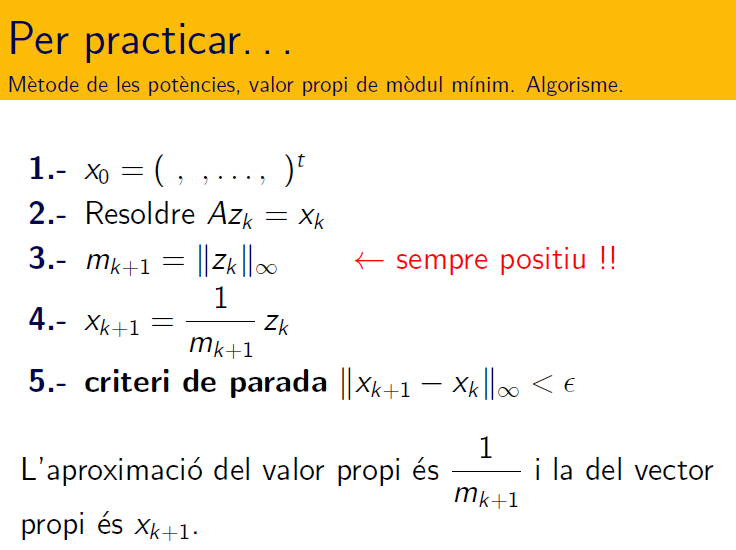

clearvars
A = [1 0 -1; 1 2 1; 2 2 3];
x = [1, -1, 1]';
k = 0; control = 1;
while (control > eps) && (k < 50)
    y = x;
    z = linsolve(A,x);
    [m,j] = max(abs(z));
    x = z/z(j);
    k = k + 1;
    control = norm(x-y,'inf');
end
vep = x

vep =     1.0000
   -1.0000
    0.0000


vap = (x'*x)/(x'*z)      % Quocient de Rayleigh

vap = 1.0000

iteracions = k-1

iteracions = 32

residu = norm(A*vep-vap*vep)

residu = 2.7195e-16

#### Exemple 3. Afegim el criteri del quocient de Rayleigh 

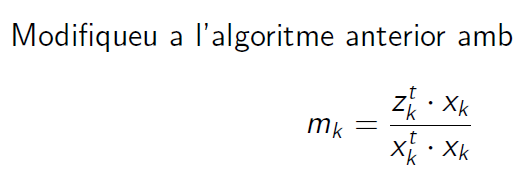

- Mètode de la potència per al valor propi de mòdul més gran

clearvars
A = [1 0 -1; 1 2 1; 2 2 3];
x = [0, 0 ,1]';
[vap,vep,iteracions,residu] = vpotencia(A,x,50,5e-5)

vap = 3.0001

vep =    -0.4550
    0.4550
    0.9100


iteracions = 8

residu = 9.2459e-05

- Mètode de la potència per al valor propi de mòdul mínim

x = [1, -1, 1]';
[vap,vep,iteracions,residu] = vpotencia_inversa(A,x,50,5e-5)

vap = 1.0000

vep =     1.3649
   -1.3649
    0.0000


iteracions = 9

residu = 5.3383e-05

#### Mètode QR per als valors propis

clearvars
A = [1 0 -1; 1 2 1; 2 2 3];
[Q,R] = qr(A);
Q*R-A   % comprovem A = QR

ans = 	1.0e+-15 *

    0.2220    0.6661    0.3331
         0         0         0
         0         0   -0.4441


k = 0; n = 1;
Ak = hess(A);   % optimització
while (k < 150 && n > 0.000001)
    [Q,R] = qr(Ak);     % Q*R = A
    Ak = R*Q;
    n = norm(tril(Ak,-1),'inf');
    k = k + 1;
end
iteracions = k

iteracions = 32

Vap = Ak

Vap =     3.0000    3.1305   -0.7303
   -0.0000    2.0000   -0.8165
         0   -0.0000    1.0000


### Part II. Practiquem ...

#### Pràctica 7.  Valors propis de mòdul màxim i mínim. 

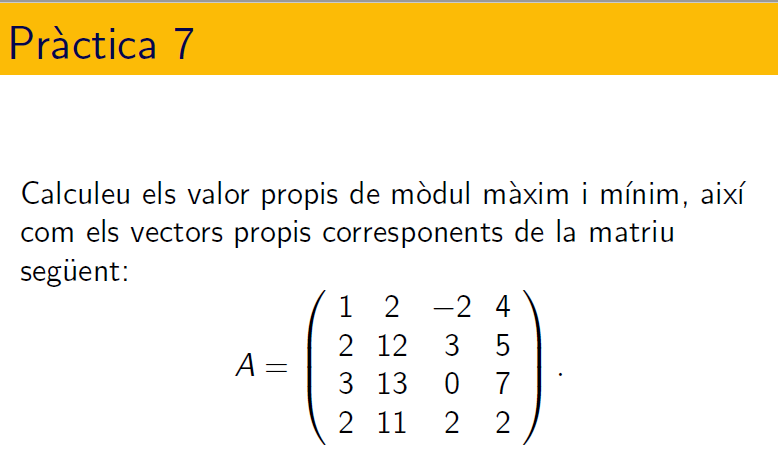

A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
x = [0 1 0 1]';
n = 50; tol = eps;
[vap,vep,iteracions,residu] = vpotencia(A,x,n,tol)

vap = 19.1820

vep =     0.1719
    1.0000
    0.9875
    0.7752


iteracions = 18

residu = 6.1535e-15

clearvars
A = [1 2 -2 4; 2 12 3 5; 3 13 0 7; 2 11 2 2];
x = [1, -1, 1, 0]';
n = 50; tol = eps;
[vap,vep,iteracions,residu] = vpotencia_inversa(A,x,n,tol)

vap = 0.0122

vep =     1.0000
   -0.2257
    0.2501
   -0.0090


iteracions = 8

residu = 5.9772e-16

#### Pràctica 8.  Quocient de Rayleigh 

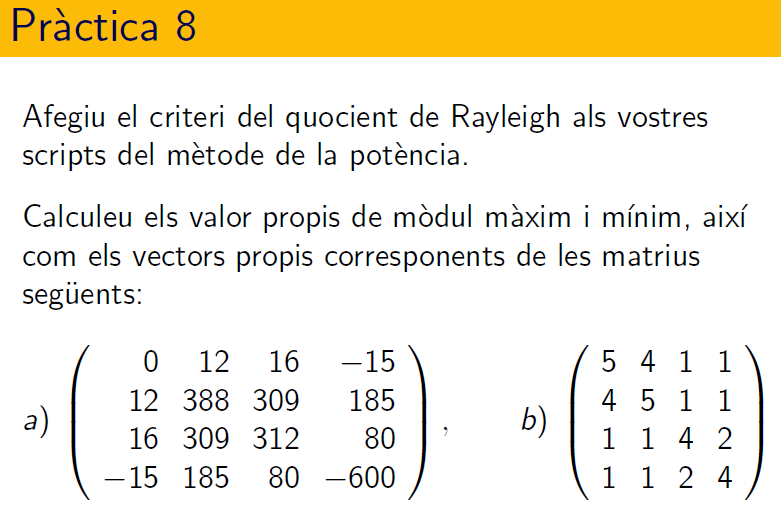

a) 

% valor mòdul màxim
A = [0 12 16 -15; 12 388 309 185; 16 309 312 80; -15 185 80 -600];
valors_vap = roots(poly(A))

valors_vap =   690.3367
 -634.6322
   45.0188
   -0.7233


x = [1 0 1 0]';
n = 200; tol = eps;
[vap,vep,iteracions,residu] = vpotencia(A, x, n, tol)

vap = 690.3367

vep =     0.0670
    2.0285
    1.7438
    0.3982


iteracions = 200

residu = 2.6585e-07

% valor mòdul mínim
x = [1 -1 -1 -1]';
[vap,vep,iteracions,residu] = vpotencia_inversa(A, x, n, tol)

vap = -0.7233

vep =     3.7645
    0.2623
   -0.4336
   -0.0711


iteracions = 200

residu = 1.5176e-14

b)

% valor mòdul màxim
x = [1 0 0 1]';
B = [5 4 1 1; 4 5 1 1; 1 1 4 2; 1 1 2 4];
[vap,vep,iteracions,residu] = vpotencia(B, x, n, tol)

vap = 10

vep =     1.1363
    1.1363
    0.5681
    0.5681


iteracions = 52

residu = 0

% valor mòdul mínim
x = [1 -1 -1 -1]';
[vap,vep,iteracions,residu] = vpotencia_inversa(B, x, n, tol)

vap = 1

vep =     1.7429
   -1.7429
   -0.0000
   -0.0000


iteracions = 24

residu = 6.6855e-16

#### Pràctica 9.  Mètode QR

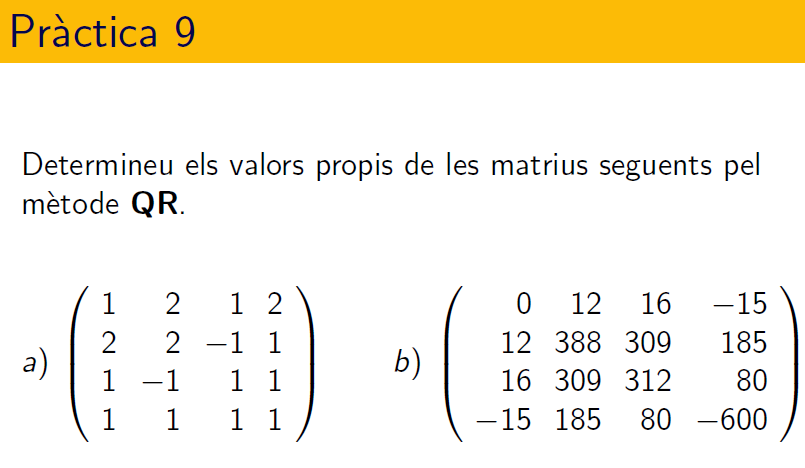

- a)

A = [1 2 1 2; 2 2 -1 1; 1 -1 1 1; 1 1 1 1];
valors_shchur = schur(A)

valors_shchur =     4.4495   -0.0216   -0.7317   -0.1988
         0   -1.3028   -0.5508   -0.1588
         0         0   -0.4495   -0.3099
         0         0         0    2.3028


[T,steps] = myqrmethod(A)

change = 1.9293e-16

H =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


T =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


steps = 71

k = 0; n = 1;
Ak = hess(A);
while (k < 150 && n > 0.000005)
    [Q,R] = qr(Ak);     % Q*R = A
    Ak = R*Q;
    n = norm(tril(Ak,-1),'inf');
    k = k + 1;
end
iteracions = k

iteracions = 29

Vap = Ak

Vap =     4.4495   -0.1151   -0.0247    0.7493
    0.0000    2.3028    0.0962   -0.3249
         0   -0.0000   -1.3028    0.5566
         0         0   -0.0000   -0.4495


residu = n

residu = 4.7362e-06

- b)

A = [0 12 16 -15; 12 388 309 185; 16 309 312 80; -15 185 80 -600];
valors_shchur = schur(A);
[T,steps] = myqrmethod(A)

change = 1.5032e-07

H =   690.3367   -0.0000   -0.0000    0.0000
   -0.0000 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0         0   -0.7233


T =   690.3367   -0.0000   -0.0000    0.0000
   -0.0000 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0         0   -0.7233


steps = 250

valors_vap = roots(poly(A))

valors_vap =   690.3367
 -634.6322
   45.0188
   -0.7233


k = 0; n = 1;
Ak = hess(A);
while (k < 150 && n > 0.000005)
    [Q,R] = qr(Ak);     % Q*R = A
    Ak = R*Q;
    n = norm(tril(Ak,-1),'inf');
    k = k + 1;
end
iteracions = k

iteracions = 150

Vap = Ak

Vap =   690.3367   -0.0007   -0.0000    0.0000
   -0.0007 -634.6322   -0.0000    0.0000
         0   -0.0000   45.0188    0.0000
         0         0   -0.0000   -0.7233


residu = n

residu = 6.7750e-04

### Part III. Valors singulars

Documentació de MATLAB®, [valors singulars](https://es.mathworks.com/help/matlab/math/singular-values.html?searchHighlight=svd&s_tid=srchtitle)

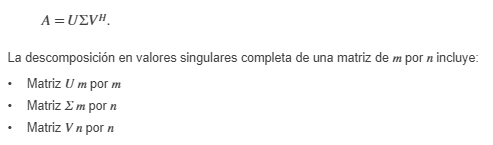

rng('default')
A = randn(6,3)               % matriu qualsevol

A =     0.5377   -0.4336    0.7254
    1.8339    0.3426   -0.0631
   -2.2588    3.5784    0.7147
    0.8622    2.7694   -0.2050
    0.3188   -1.3499   -0.1241
   -1.3077    3.0349    1.4897


[U,S,V] = svd(A)             % U*S*V'-A

U =    -0.0721    0.0747   -0.6808    0.4983   -0.2036   -0.4857
   -0.0618    0.6554   -0.2259   -0.6432    0.1342   -0.2895
    0.6923   -0.2595    0.2151   -0.0991    0.1551   -0.6109
    0.3526    0.6969    0.2965    0.5244    0.0805    0.1434
   -0.2241   -0.0850   -0.1006    0.1872    0.9463   -0.0433
    0.5806   -0.0677   -0.5840   -0.1346    0.1203    0.5335


S =     6.0992         0         0
         0    2.7539         0
         0         0    1.2867
         0         0         0
         0         0         0
         0         0         0


V =    -0.3677    0.9043   -0.2167
    0.9065    0.4006    0.1337
    0.2077   -0.1473   -0.9670


U*S*V'-A

ans = 	1.0e+-14 *

    0.0444   -0.0500   -0.0666
    0.3109    0.1665   -0.0611
   -0.2665    0.3997    0.0777
    0.2220    0.3553   -0.0028
    0.0056   -0.1554   -0.0236
   -0.1998    0.3997    0.0444


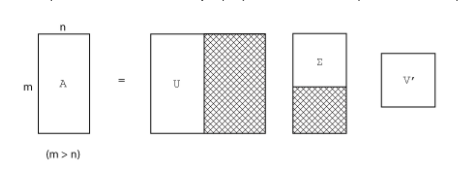

[U,S,V] = svd(A,0)

U =    -0.0721    0.0747   -0.6808
   -0.0618    0.6554   -0.2259
    0.6923   -0.2595    0.2151
    0.3526    0.6969    0.2965
   -0.2241   -0.0850   -0.1006
    0.5806   -0.0677   -0.5840


S =     6.0992         0         0
         0    2.7539         0
         0         0    1.2867


V =    -0.3677    0.9043   -0.2167
    0.9065    0.4006    0.1337
    0.2077   -0.1473   -0.9670


U*S*V'-A

ans = 	1.0e+-14 *

    0.0444   -0.0500   -0.0666
    0.3109    0.1665   -0.0611
   -0.2665    0.3997    0.0777
    0.2220    0.3553   -0.0028
    0.0056   -0.1554   -0.0236
   -0.1998    0.3997    0.0444


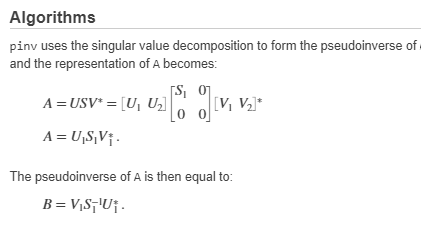

pinversa = pinv(A), B = V*inv(S)*U'

pinversa =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


B =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


% pseudoinversa compleix que BAB = B, ABA = A
(B*A)*B, (A*B)*A

ans =     0.1436    0.2570   -0.1632    0.1576    0.0025    0.0412
   -0.0706    0.0627    0.0875    0.1846   -0.0561    0.0158
    0.5052    0.1326   -0.1242   -0.2481    0.0726    0.4624


ans =     0.5377   -0.4336    0.7254
    1.8339    0.3426   -0.0631
   -2.2588    3.5784    0.7147
    0.8622    2.7694   -0.2050
    0.3188   -1.3499   -0.1241
   -1.3077    3.0349    1.4897


#### Pràctica 10.  Descomposició en valors singulars

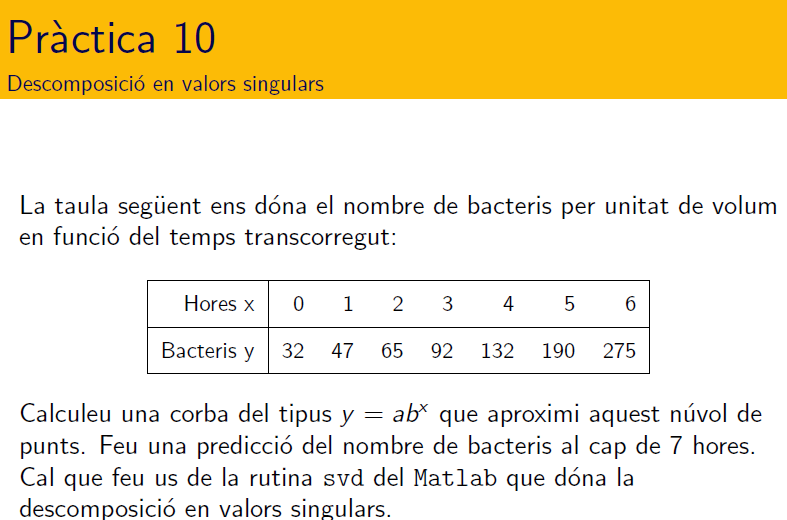

% TODO
x = [0 1 2 3 4 5 6]';
y = [32 47 65 92 132 190 275]';
A = [0 1 2 3 4 5 6; ones(size(x))']'

A =      0     1
     1     1
     2     1
     3     1
     4     1
     5     1
     6     1


% log y = log a + x log b
b = log(y)

b =     3.4657
    3.8501
    4.1744
    4.5218
    4.8828
    5.2470
    5.6168


% coef = linsolve(A, b)
B = A'*A; c = A'*b;
coeff = exp(linsolve(B,c))

coeff =     1.4270
   32.1469


f = @(t) coeff(2).*coeff(1).^t;
z = f(7)

z = 387.2741

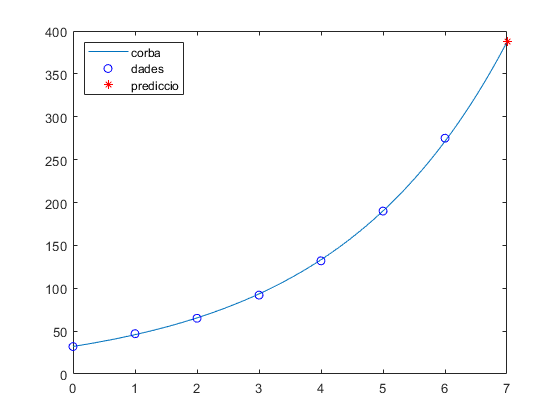

t = linspace(0,7);
plot(t,f(t),x,y,'bo',7,f(7),'r*'), legend('corba','dades','prediccio','Location','northwest')

Func myqrmethod

function [H,steps] = myqrmethod(A)
% Computes all the eigenvalues of a matrix using the QR method.
% Input: A -- square matrix
% Outputs: E -- vector of eigenvalues
% steps -- the number of iterations it took
[m n] = size(A);
if m ~= n
    warning('The input matrix is not square.')
return
end
% Set up initial estimate
H = hess(A);
E = diag(H);
change = 1;
steps = 0;
% loop while estimate changes
while (change > eps && steps < 250)
    Eold = E;
    % apply QR method
    [Q R] = qr(H);
    H = R*Q;
    % test change
    change = norm(tril(H,-1));
    steps = steps +1;
end
change,H
end
%---------

`Document preparat per M. Àngela Grau Gotés, 16 de març de 2021`